# Neural Networks on Chaotic Systems

#### Making Training Set

To implement neural networks it is necessary to have a training set and a testing set. The training set is used for the neural networks to learn the model, while the testing set is used to provide an unbiased evaluation based on the learned model.

The function below creates a traning set containing pairings of locations at time "t" and "t + dt". This will be used for the neural networks to be able to predict the future locations of points. The function also plots the initial points in squares and their trajectories until the desired total time.

%{
function [in, out] = trainingData(handler)
in = [];
out = [];
dt = .01;
totalTime = 10;
time = 0:dt:totalTime;
for i = 1:100
    x0 = 20 * (rand - 1);
    y0 = 20 * (rand - 1);
    z0 = 20 * (rand - 1);
    [time, triple] = ode45(handler,time, [x0; y0; z0]);
    x = triple(:, 1);
    y = triple(:, 2);
    z = triple(:, 3);
    in=[in; triple(1:end-1,:)]; 
    out=[out; triple(2:end,:)]; %dt to the future of "in"
    plot3(x, y, z); 
    hold on;
    plot3(x0, y0, z0,'bs');
    xlabel('x');
    ylabel('y');
    zlabel('z');
end
hold off;
end
%}

Clean workspace

close all; clear all; clc;

### [Lorenz Equation](https://en.wikipedia.org/wiki/Lorenz_system) 


$$\begin{array}{l}
\frac{\mathrm{dx}}{\mathrm{dt}}=\sigma \left(y-x\right)\\
\frac{\mathrm{dy}}{\mathrm{dt}}=x\left(\rho -z\right)-y\\
\frac{\mathrm{dz}}{\mathrm{dt}}=\mathrm{xy}-\beta z
\end{array}$$


The Lorenz Equation consists of 3 non-linear differential equations with Prandtl number "σ", Rayleigh number "ρ" and another constant "β".

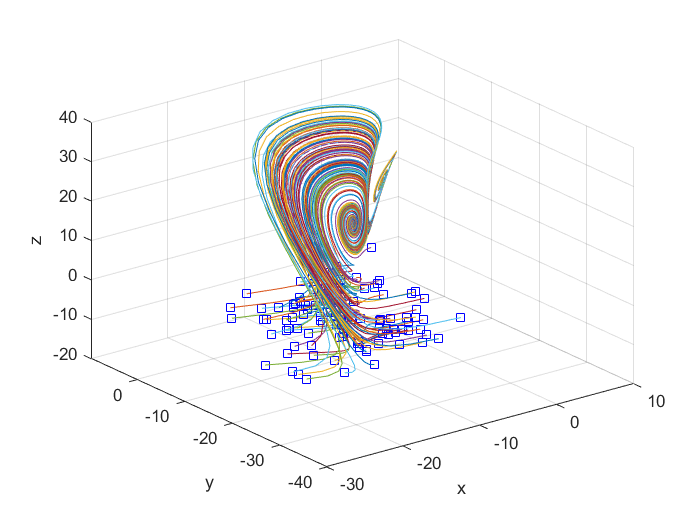

%σ=28, ρ=10, β=8/3
LorenzEq = @(t, x) ([28 * (x(2) - x(1)); ...
    x(1) * (10 - x(3)) - x(2); ...
    x(1) * x(2) - (8/3) * x(3)]);    
[LorenzIn, LorenzOut] = trainingData(LorenzEq);

### Rossler Attractor


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=-y-x\\
\frac{\mathrm{dy}}{\mathrm{dt}}=x+\mathrm{ay}\\
\frac{\mathrm{dz}}{\mathrm{dt}}=b+z\left(x-c\right)\;
\end{array}$$


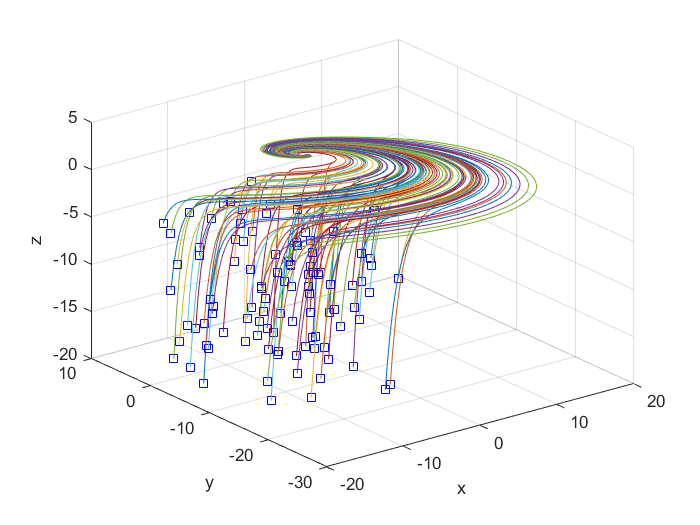

%a=0.1, b=0.1, c=14
RosslerEq = @(t, x) ([-x(2) - x(1); ...
    x(1) + 0.1 * x(2); ...
    0.1 + x(3) * (x(1) - 14)]);   
[RosslerIn, RosslerOut] = trainingData(RosslerEq);

### Chen Attractor


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=a\left(y-x\right)\\
\frac{\textrm{dy}}{\textrm{dt}}=\left(c-a\right)x-\mathrm{xz}+\mathrm{cy}\\
\frac{\textrm{dz}}{\textrm{dt}}=\mathrm{xy}-\mathrm{bz}
\end{array}$$


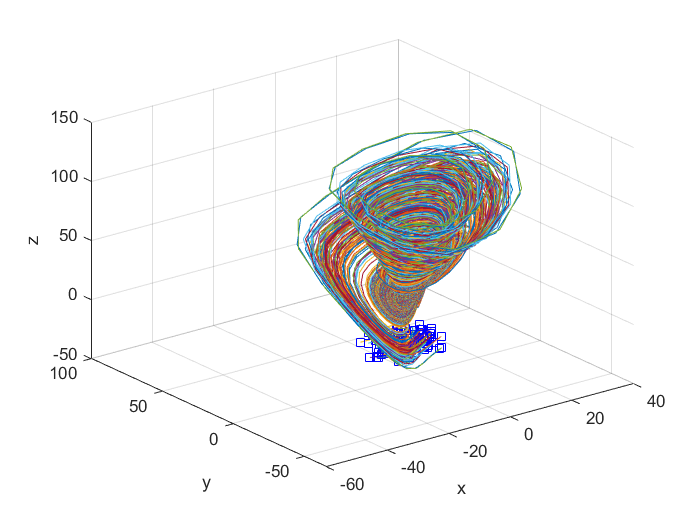

%a=35, b=3, c=28
ChenEq = @(t, x) ([35 * (x(2) - x(1)); ...
    (28 - 35) * x(1) - x(1) * x(3) + 28 * x(2); ...
    x(1) * x(2) - 3 * x(3)]); 
[ChenIn, ChenOut] = trainingData(ChenEq);

### Pan-Xu-Zhou Attractor


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=a\left(y-x\right)\\
\frac{\textrm{dy}}{\textrm{dt}}=\mathrm{cx}-\textrm{xz}\\
\frac{\textrm{dz}}{\textrm{dt}}=\textrm{xy}-\textrm{bz}
\end{array}$$


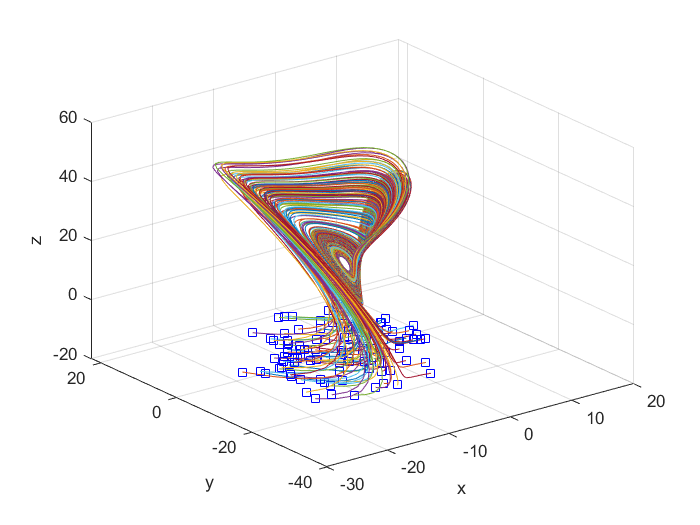

%a=10, b=8/3, c=16
PanXuZhouEq = @(t, x) ([10 * (x(2) - x(1)); ...
    16 * x(1) - x(1) * x(3); ...
    x(1) * x(2) - (8/3) * x(3)]); 
[PanXuZhouIn, PanXuZhouOut] = trainingData(PanXuZhouEq);

### Hyperchaotic 4D System


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=x\left(1-y\right)+\alpha z\\
\frac{\textrm{dy}}{\textrm{dt}}=\beta \left(x^2 -1\right)y\\
\frac{\textrm{dz}}{\textrm{dt}}=\gamma \left(1-y\right)v\\
\frac{\mathrm{dv}}{\mathrm{dt}}=\eta z
\end{array}$$


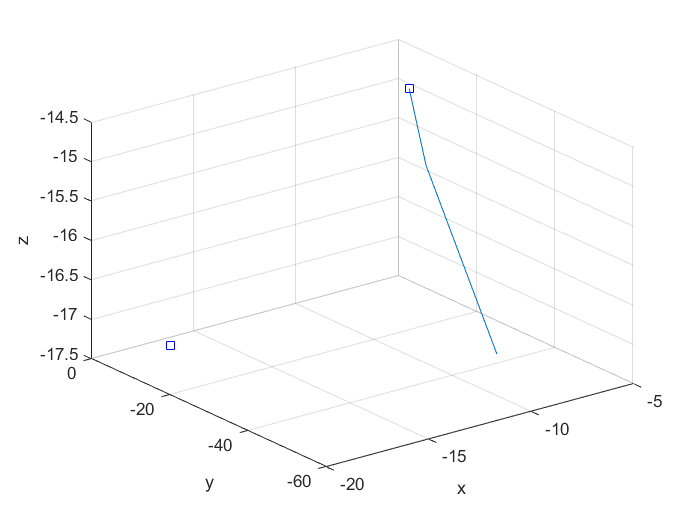

Error using odearguments (line 21)
When the first argument to ode45 is a function handle, the tspan argument must have at least two elements.

Error in ode45 (line 115)
  odearguments(FcnHandlesUsed, solver_name, ode, tspan, y0, options, varargin);

Error in NeuralNet

%α=-2, β=1, γ=0.2, η=1
Hyperchaotic4DEq = @(t, x) ([x(1) * (1 - x(2)) + (-2) * x(3); ...
    1 * (x(1) * x(1) - 1) * x(2); ...
    0.2 * (1 - x(2)) * x(4); ...
    1 * x(3)]); 

[Hyperchaotic4DIn, Hyperchaotic4DOut] = trainingData4D(Hyperchaotic4DEq);

### Hyperchaotic 5D System


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=a\left(y-x\right)\\
\frac{\textrm{dy}}{\textrm{dt}}=\mathrm{cx}+\mathrm{dy}-\mathrm{xz}+w\\
\frac{\textrm{dz}}{\textrm{dt}}=-\mathrm{bz}+x^2 \\
\frac{\textrm{du}}{\textrm{dt}}=\mathrm{ey}+\mathrm{fu}\\
\frac{\mathrm{dw}}{\mathrm{dt}}=-\mathrm{rx}-\mathrm{kw}
\end{array}$$


%a=35, b=7, c=35, d=-5, e=10.6, f=1, r=5, k=0.05
Hyperchaotic5DEq = @(t, x) ([35 * (x(2) - x(1));
    35 * x(1) + (-5) * x(2) - x(1) * x(3) + x(5);
    -7 * x(3) + x(1) * x(1);
    10.6 * x(2) + 1 * x(4);
    -5 * x(1) - 0.05 * x(5)]);
[Hyperchaotic5DIn, Hyperchaotic5DOut] = trainingData5D(Hyperchaotic5DEq);

### [Neural Networks](https://skymind.ai/wiki/neural-network)

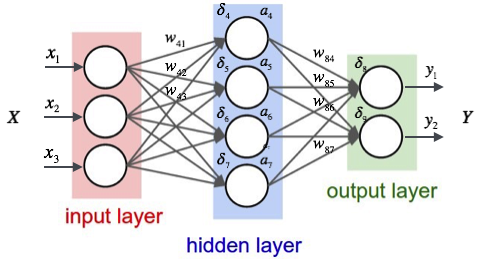

Neural networks are a set of algorithms to find patterns and in this case, the trajectory of the points in the chaotic system. Neural Networks consist of the input, output, and the hidden layer, and 3 layers were used for this project. Multiple-layered networks usually perform better than single-layer network because one layer usually cannot produce enough non-linearity to be able to classify the data that is fed to the network. These non-linearities are affected by the activation functions that are used in each of the hidden layers.

The activation functions that are used for the hidden layers are elliot symmetric sigmoid, log-sigmoid, hyperbolic tangent sigmoid. These functions have different strengths and weaknesses. The **log-sigmoid** is nice for problems with probability because the range is between 0 and 1, but the function can cause the neural network to get stuck at the training time. The **hyperbolic tangent** maps negative inputs to negative and zero inputs to zero and is a good for classification between two classes. The **elliot symmetric sigmoid **is fast to calculate because of the absence of exponential or trigonometric functions but requires more training iterations. A **linear function** is used for the output layer because it is known that a linear function is suitable for the output.

A number of 5 neurons per hidden layer was chosen so that the training of neural network does not take too much time. Note that you can stop training the neural network when you see that the error is very small.

%{
function [nn] = NN(in, out) 
nn = feedforwardnet([5 5 5 10]);
nn.layers{1}.transferFcn = 'elliotsig';
nn.layers{2}.transferFcn = 'logsig';
nn.layers{3}.transferFcn = 'tansig';
nn.layers{4}.transferFcn = 'purelin';
nn = train(net,in.',out.');
end
%}

#### Testing Set

Now we can choose a random initial point and compare the trajectory based on using ODE45 and the neural networks model. The graphs that show the deviations on the x, y, and z-axes are also shown.

%{
function [] = testingData(handler, nn)
figure(2)
dt = .01;
totalTime = 10;
time = 0:dt:totalTime;
x0 = 20 * (rand - 1);
y0 = 20 * (rand - 1);
z0 = 20 * (rand - 1);
[time, triple] = ode45(handler,time, [x0; y0; z0]);
x = triple(:, 1);
y = triple(:, 2);
z = triple(:, 3);
figure(2);
plot3(x, y, z);
hold on;
grid on;
xlabel('x');
ylabel('y');
zlabel('z');

testTraj(1,:)= [x0; y0; z0];
curr = [x0; y0; z0];
for i = 2 : length(time)
    next = nn(curr);
    testTraj(i, :) = next.';
    curr = next;
end
    
plot3(testTraj(:, 1), testTraj(:, 2), testTraj(:, 3))
legend('ODE45','Neural Networks');
plot3(x0, y0, z0,'bs');
hold off;

figure(3)
subplot(3,1,1);
plot(time,x,time,testTraj(:,1));
xlabel('time');
ylabel('x');
legend('ODE45','Neural Networks')
subplot(3,1,2); 
plot(time, y,time,testTraj(:,2));
xlabel('time');
ylabel('y');
legend('ODE45','Neural Networks')
subplot(3,1,3);
plot(time,z,time,testTraj(:,3));
xlabel('time');
ylabel('z');
legend('ODE45','Neural Networks');
end
%}

For 5D hyperchaotic system, the 3D graph on x, y, and z axes is shown, but you may easily change that by changing the parameters in testingData5D function. The deviations on the x, y, z, u, and w axes can be seen in the five graphs.

%Lorenz
nn_Lorenz = NN(LorenzIn, LorenzOut);
testingData(LorenzEq, nn_Lorenz);
%Rossler
nn_Rossler = NN(RosslerIn, RosslerOut);
testingData(RosslerEq, nn_Rossler);
%Chen
nn_Chen = NN(ChenIn, ChenOut);
testingData(ChenEq, nn_Chen);
%PanXuZhou
nn_PanXuZhou = NN(PanXuZhouIn, PanXuZhouOut);
testingData(PanXuZhouEq, nn_PanXuZhou);
%5D Hyperchaotic
nn_Hyperchaotic5D = NN(Hyperchaotic5DIn, Hyperchaotic5DOut);
testingData5D(Hyperchaotic5DEq, nn_Hyperchaotic5D);

### Helper functions

function [in, out] = trainingData(handler)
in = [];
out = [];
dt = .01;
totalTime = 10;
time = 0:dt:totalTime;
for i = 1:100
    x0 = 20 * (rand - 1);
    y0 = 20 * (rand - 1);
    z0 = 20 * (rand - 1);
    [time, triple] = ode45(handler,time, [x0; y0; z0]);
    x = triple(:, 1);
    y = triple(:, 2);
    z = triple(:, 3);
    in=[in; triple(1:end-1,:)]; 
    out=[out; triple(2:end,:)]; %dt to the future of "in"
    plot3(x, y, z); 
    hold on;
    grid on;
    plot3(x0, y0, z0,'bs');
    xlabel('x');
    ylabel('y');
    zlabel('z');
end
hold off;
end

function [in, out] = trainingData4D(handler)
in = [];
out = [];
dt = .01;
totalTime = 10;
time = 0:dt:totalTime;
for i = 1:100
    x0 = 20 * (rand - 1);
    y0 = 20 * (rand - 1);
    z0 = 20 * (rand - 1);
    v0 = 20 * (rand - 1);
    [time, quad] = ode45(handler,time, [x0; y0; z0; v0]);
    x = quad(:, 1);
    y = quad(:, 2);
    z = quad(:, 3);
    v = quad(:, 4);
    in=[in; quad(1:end-1,:)]; 
    out=[out; quad(2:end,:)]; %dt to the future of "in"
    plot3(x, y, z); 
    hold on;
    grid on;
    plot3(x0, y0, z0,'bs');
    xlabel('x');
    ylabel('y');
    zlabel('z');
end
hold off;
end

function [in, out] = trainingData5D(handler)
in = [];
out = [];
dt = .01;
totalTime = 10;
time = 0:dt:totalTime;
for i = 1:100
    x0 = 20 * (rand - 1);
    y0 = 20 * (rand - 1);
    z0 = 20 * (rand - 1);
    u0 = 20 * (rand - 1);
    w0 = 20 * (rand - 1);
    [time, five] = ode45(handler,time, [x0; y0; z0; u0; w0]);
    x = five(:, 1);
    y = five(:, 2);
    z = five(:, 3);
    u = five(:, 4);
    w = five(:, 5);
    in=[in; five(1:end-1,:)]; 
    out=[out; five(2:end,:)]; %dt to the future of "in"
    plot3(x, y, z); 
    hold on;
    grid on;
    plot3(x0, y0, z0,'bs');
    xlabel('x');
    ylabel('y');
    zlabel('z');
end
hold off;
end

function [nn] = NN(in, out) 
nn = feedforwardnet([5 5 5 10]);
nn.layers{1}.transferFcn = 'elliotsig';
nn.layers{2}.transferFcn = 'logsig';
nn.layers{3}.transferFcn = 'tansig';
nn.layers{4}.transferFcn = 'purelin';
nn = train(nn,in.',out.');
end

function [] = testingData(handler, nn)
figure(2)
dt = .01;
totalTime = 10;
time = 0:dt:totalTime;
x0 = 20 * (rand - 1);
y0 = 20 * (rand - 1);
z0 = 20 * (rand - 1);
[time, triple] = ode45(handler,time, [x0; y0; z0]);
x = triple(:, 1);
y = triple(:, 2);
z = triple(:, 3);
figure(2);
plot3(x, y, z);
hold on;
grid on;
xlabel('x');
ylabel('y');
zlabel('z');

testTraj(1,:)= [x0; y0; z0];
curr = [x0; y0; z0];
for i = 2 : length(time)
    next = nn(curr);
    testTraj(i, :) = next.';
    curr = next;
end
    
plot3(testTraj(:, 1), testTraj(:, 2), testTraj(:, 3))
legend('ODE45','Neural Networks');
plot3(x0, y0, z0,'bs');
hold off;

figure(3)
subplot(3,1,1);
plot(time,x,time,testTraj(:,1));
xlabel('time');
ylabel('x');
legend('ODE45','Neural Networks')
subplot(3,1,2); 
plot(time, y,time,testTraj(:,2));
xlabel('time');
ylabel('y');
legend('ODE45','Neural Networks')
subplot(3,1,3);
plot(time,z,time,testTraj(:,3));
xlabel('time');
ylabel('z');
legend('ODE45','Neural Networks');
end

function [] = testingData5D(handler, nn)
figure(2)
dt = .01;
totalTime = 10;
time = 0:dt:totalTime;
x0 = 20 * (rand - 1);
y0 = 20 * (rand - 1);
z0 = 20 * (rand - 1);
u0 = 20 * (rand - 1);
w0 = 20 * (rand - 1);
[time, five] = ode45(handler,time, [x0; y0; z0; u0; w0]);
x = five(:, 1);
y = five(:, 2);
z = five(:, 3);
u = five(:, 4);
w = five(:, 5);
figure(2);
plot3(x, y, z);
hold on;
grid on;
xlabel('x');
ylabel('y');
zlabel('z');

testTraj(1,:)= [x0; y0; z0; u0; w0];
curr = [x0; y0; z0; u0; w0];
for i = 2 : length(time)
    next = nn(curr);
    testTraj(i, :) = next.';
    curr = next;
end
    
plot3(testTraj(:, 1), testTraj(:, 2), testTraj(:, 3))
legend('ODE45','Neural Networks');
plot3(x0, y0, z0,'bs');
hold off;

figure(3)
subplot(5,1,1);
plot(time,x,time,testTraj(:,1));
xlabel('time');
ylabel('x');
legend('ODE45','Neural Networks')
subplot(5,1,2); 
plot(time, y,time,testTraj(:,2));
xlabel('time');
ylabel('y');
legend('ODE45','Neural Networks')
subplot(5,1,3);
plot(time,z,time,testTraj(:,3));
xlabel('time');
ylabel('z');
subplot(5,1,4);
plot(time,u,time,testTraj(:,4));
xlabel('time');
ylabel('u');
subplot(5,1,5);
plot(time,x,time,testTraj(:,5));
xlabel('time');
ylabel('w');
legend('ODE45','Neural Networks');
end